Aerofoil

## **Aerofoil shape**

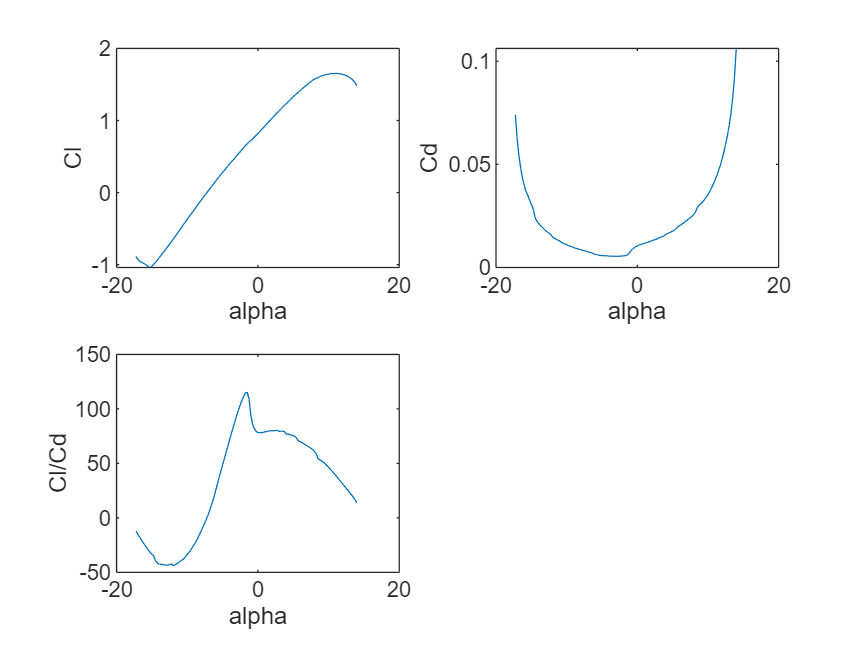

airfoil = Airfoil();
airfoil = airfoil.readPolar("xf-sc21010-il-1000000.csv");
airfoil = airfoil.readShape("sc21010.dat.txt");
airfoil = airfoil.interpShape(9);
figure(1)
clf;
airfoil.plotPolar()

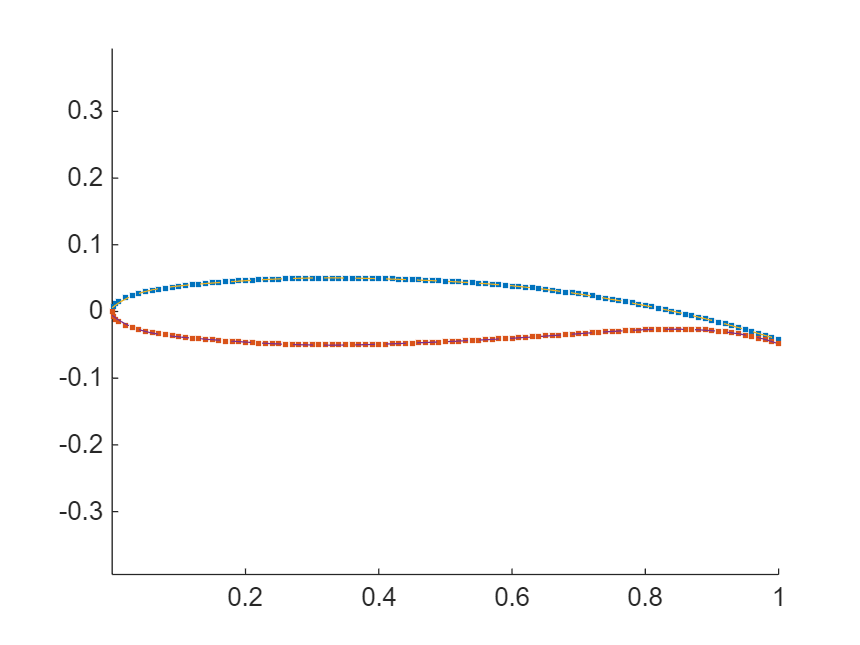


figure(2)
clf;
airfoil.plotShape()


airfoil

airfoil =   Airfoil with properties:

            alpha: [125×1 double]
               Cl: [125×1 double]
               Cd: [125×1 double]
       uppershape: [103×2 double]
       lowershape: [103×2 double]
    upperShapefun: @(x_c)polyval(p_upper,x_c)
    lowerShapefun: @(x_c)polyval(p_lower,x_c)
              x_c: [0 0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0261 0.0281 0.0301 0.0321 0.0341 0.0361 0.0381 0.0401 0.0421 0.0441 0.0461 0.0481 0.0501 0.0521 0.0541 0.0561 0.0581 0.0601 … ] (1×500 double)
           t_cfun: @(x_c)polyval(p_thickness,x_c)
              t_c: 0.1007
             x_cm: 0.3246


Wing Definition:

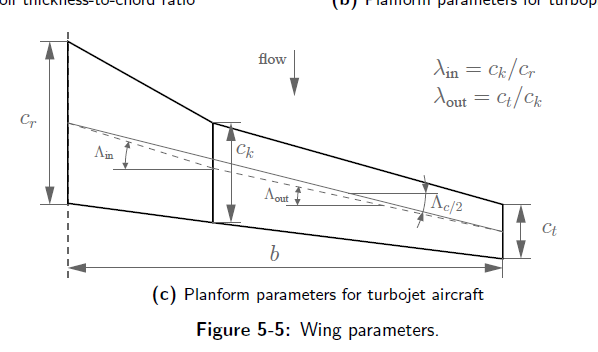

Define wing:

wing = WingGeometry();
wing.cr = 10;
wing.ck = 10;
wing.ct = 8;
wing.s = 65/2;
wing.Lambdain50 = 0*pi/180;
wing.Lambdaout50 = 0*pi/180;
wing.yk = wing.s*0.3;
wing = wing.calcSref()

wing =   WingGeometry with properties:

             cr: 10
             ck: 10
             ct: 8
              s: 32.5000
             yk: 9.7500
     Lambdain50: 0
    Lambdaout50: 0
           SREF: 604.5000
              N: []
             Sc: []
         stripy: []
             AR: 3.4946
            Sin: 97.5000
           Sout: 204.7500
            MAC: 9.3000


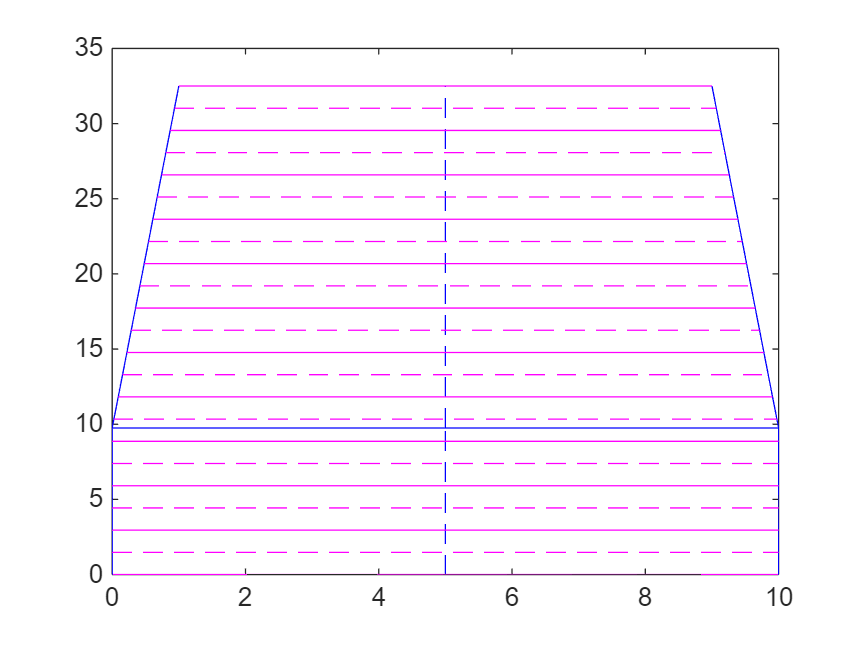

wing.N = 11;
figure(3)
clf;
axis equal
wing.plotWing()
wing.c_at_y(10);
wing = wing.createStrips();
wing.plotStrips();

wing = wing.calcSc()

wing =   WingGeometry with properties:

             cr: 10
             ck: 10
             ct: 8
              s: 32.5000
             yk: 9.7500
     Lambdain50: 0
    Lambdaout50: 0
           SREF: 604.5000
              N: 11
             Sc: [14.7727 14.7727 14.7727 14.6384 14.3123 13.9286 13.5449 13.1612 12.7774 12.3937 12.0100]
         stripy: [1.4773 4.4318 7.3864 10.3409 13.2955 16.2500 19.2045 22.1591 25.1136 28.0682 31.0227]
             AR: 3.4946
            Sin: 97.5000
           Sout: 204.7500
            MAC: 9.3000


Cruise Condition

%Chord length
c = 4;
cruise = AirCondition()

cruise =   AirCondition with properties:

      M: []
      V: []
      h: []
    rho: []
      T: []
      a: []
      P: []
     nu: []
     mu: []
     Re: []


cruise.M = 0.83;
cruise.h = convlength(39000, 'ft','m');
cruise = cruise.init(wing.MAC)

cruise =   AirCondition with properties:

      M: 0.8300
      V: 244.9078
      h: 1.1887e+04
    rho: 0.3164
      T: 216.6500
      a: 295.0696
      P: 1.9677e+04
     nu: 4.4930e-05
     mu: 1.4216e-05
     Re: 5.0693e+07


## Lifting Line Theory

Iteration 100001: Max relative difference = 0.37145732138745790607


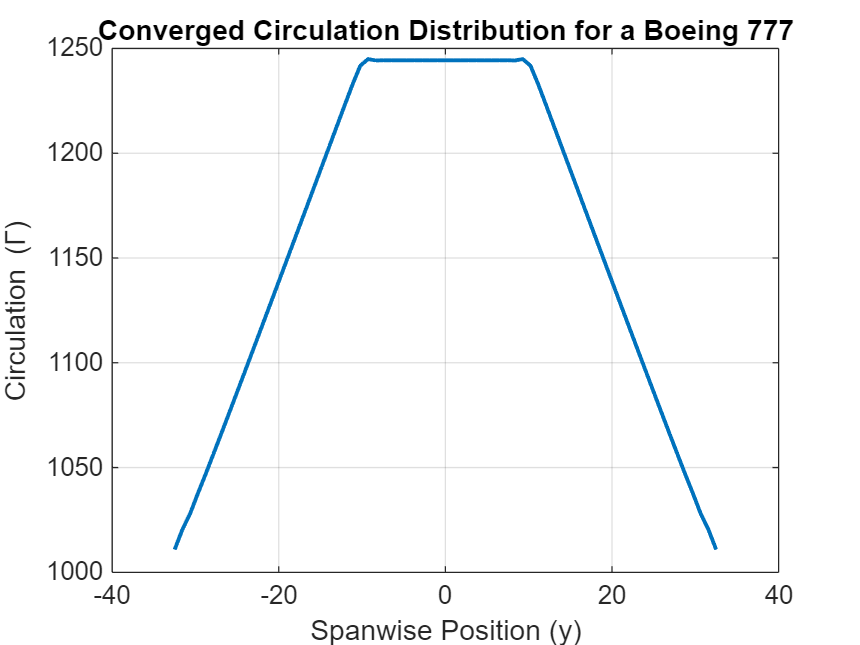

Total Lift Coefficient (C_L): 1.031347
Total Induced Drag (CDi): 0.004306


CLclean = 1.0313

CDi = 0.0043

[CLclean, CDi] = LLE(wing,airfoil,cruise,71,1e-5)

Swet_SrefWing = 2.2;
Swet_SrefBody = 5;
l_d = 10;

## Drag Model, Ref15

## Friction Drag

CDF = CDFfun(cruise.M, cruise.Re, wing, airfoil.x_cm, airfoil.t_c, l_d, Swet_SrefWing, Swet_SrefBody)

CDF = 0.0096

## Wave Drag

Integration of drag produced by each strip gives the total wave drag coefficient

CDW = CDWfun(wing,@Clfun,cruise.M,airfoil.t_c)

CDW = 0.0032

Total Drag

CD0 = CDF + CDW + CDi

CD0 = 0.0171

## Wing Weight

W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8
Wpay = 9.81*(W_crew + W_payload)

Wpay = 5.0412e+05

Wto = 4.3895*1e5*9.81

Wto = 4.3061e+06

nult = 3.75; %Chatgpt, b777
range = convlength(7500, 'naut mi','m');

Ww = wingWeightLTH(wing,airfoil.t_c,Wto)

Unrecognized function or variable 't_c'.

%Ww = wingWeightHowe(wing,Wpay,Wto,nult,t_c,V,range*1e03)
mw = Ww/9.81 %one wing

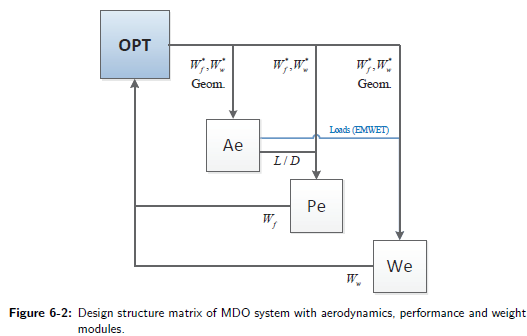

function Cl = Clfun(y)
    Cl = 0.7*y/y;
end